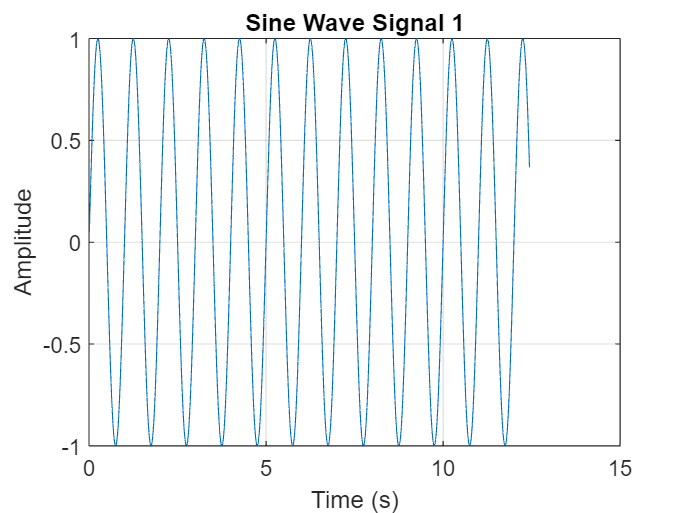

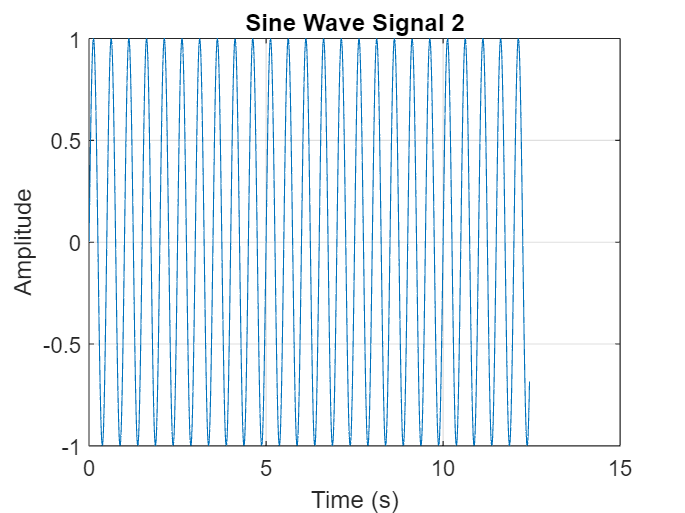

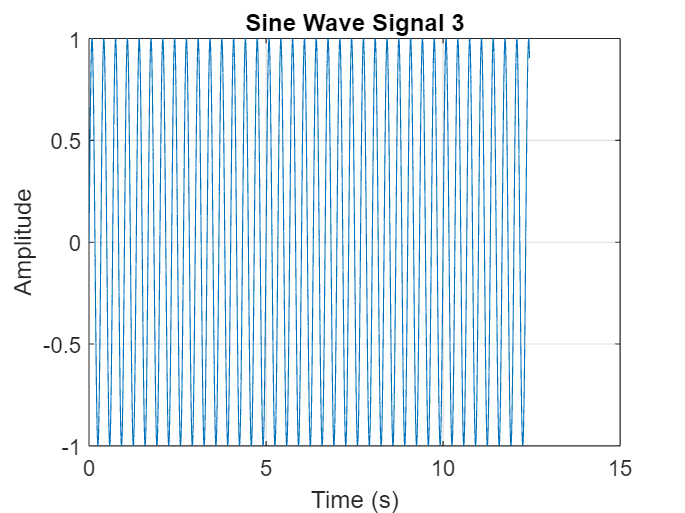

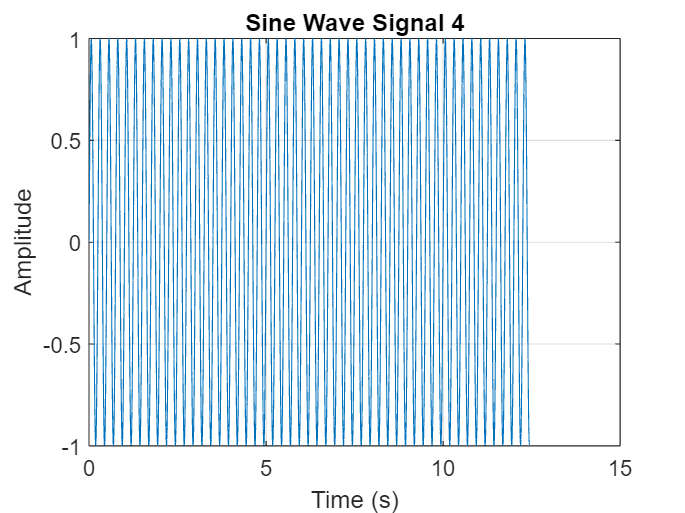

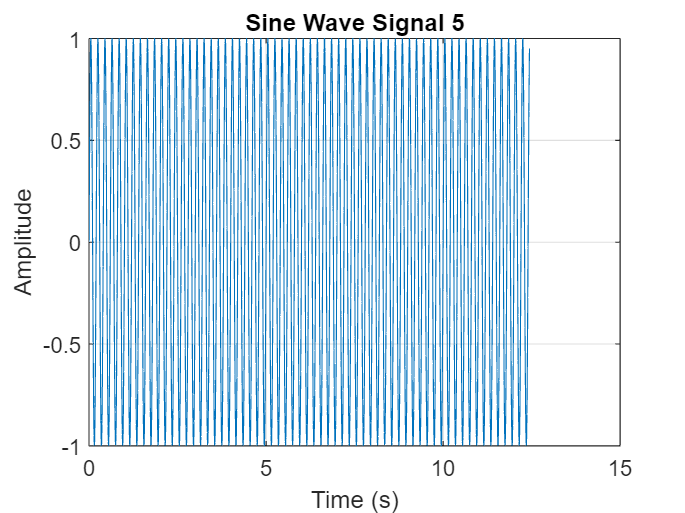

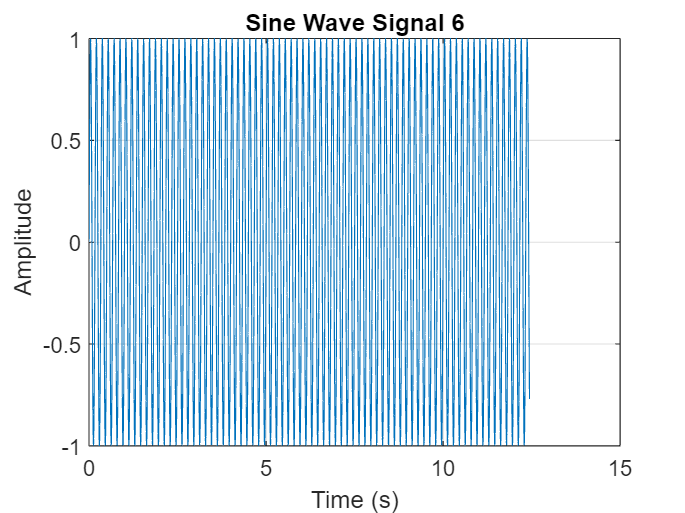

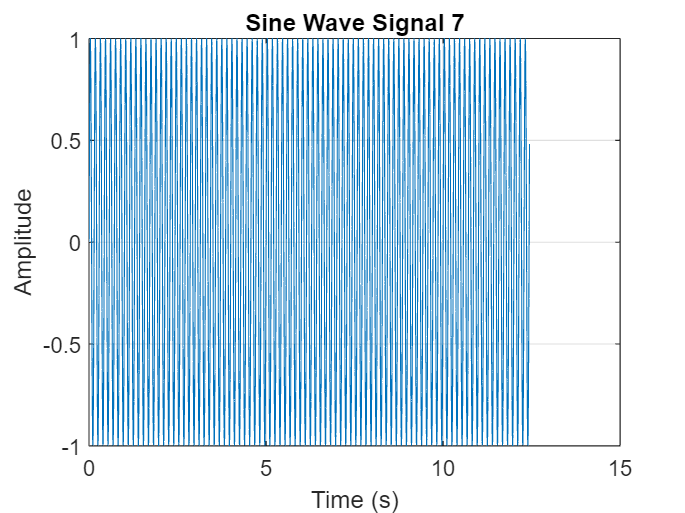

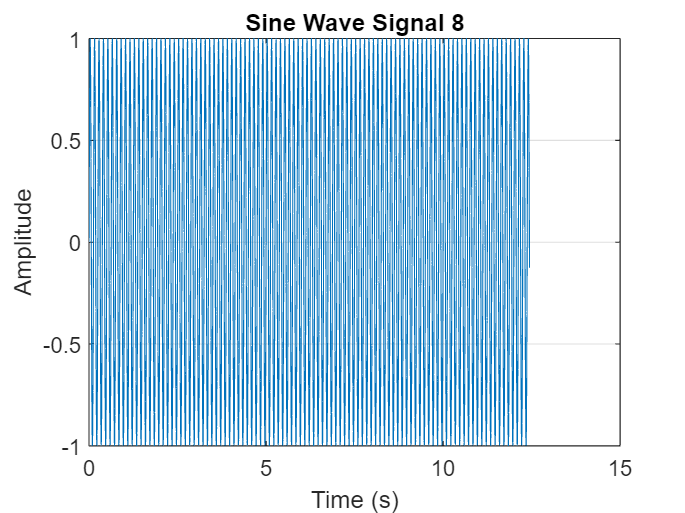

% Parameters
A = 1;          % Amplitude
f = 50;         % Frequency in Hz
sampling_rate = 3200;   % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                  % Period of one cycle
duration = num_cycles * T;  % Total duration of the signal
num_samples = duration * sampling_rate + 1;  % Number of samples
t = linspace(0, duration, num_samples);  

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;

% Generate and save sine wave signals
for i = 1:num_signals
    % Generate sine wave signal
    omega = 2 * pi * (i);  % Angular frequency
    signal = A * sin(omega * t);
    % Plot and save signal to PNG
    figure;
    plot(t, signal);
    title(['Sine Wave Signal ', num2str(i)]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end